# Limited Slip Differential with Clutches

This example shows a comparison between the behavior of an open differential and a limited slip differential with clutch packs. The limited slip differential is modeled using components from the Gears library and Clutches library in Simscape™ Driveline™. Wheel slip is limited by clutches that engage when the torque applied to the input of the differential exceeds a threshold. The clutches lock the differential so that the output shafts of the differential spin at the same speed.

The test surface includes an icy patch under the left wheel. This effect is introduced using the variable-friction coefficient variant of the Tire (Magic Formula) block. Comparing the two differentials on the same test surface shows that the limited slip differential locks up under the split surface road condition.

## Model

open_system('LimitedSlipDifferentialWithClutches')

set_param(find_system('LimitedSlipDifferentialWithClutches','MatchFilter', @Simulink.match.allVariants,'FindAll', 'on','type','annotation','Tag','ModelFeatures'),'Interpreter','off')

## Limited Slip Differential Subsystem

open_system('LimitedSlipDifferentialWithClutches/Limited Slip Differential','force')

## Tires Limited Slip Differential Subsystem

open_system('LimitedSlipDifferentialWithClutches/Tires Limited Slip Differential','force')

## Simulation Results from Simscape Logging

The plot below shows the performance of an open and a limited slip differential on a split surface (ice and tarmac). The limited slip differential locks when the left wheel encounters the icy patch, and the left and right wheel speeds remain the same. The open differential does not lock and applies the same torque to both shafts. The result is that the left wheel loses traction on the icy patch and slips.

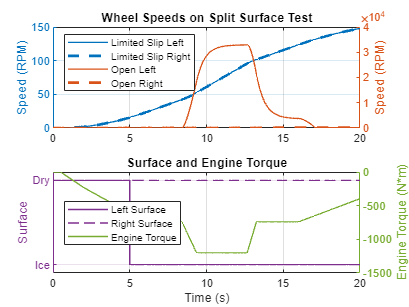

LimitedSlipDifferentialWithClutchesPlot1Speeds;
subplot(2,1,1)      % Commands to ensure lower limit on y-axis is exactly 0
yyaxis left
temp_ylim = ylim;
set(gca,'YLim',[0 temp_ylim(2)]);

The plot below shows the performance of open and a limited slip differential on a split surface (ice and tarmac). The limited slip differential locks instantly when the left wheel encounters the icy patch. As a result, the wheels turn at the same speed and more torque is applied to the wheel on the high friction surface. The open differential does not lock. The same torque is applied to both wheels, resulting in the left wheel slipping extensively on the icy patch.

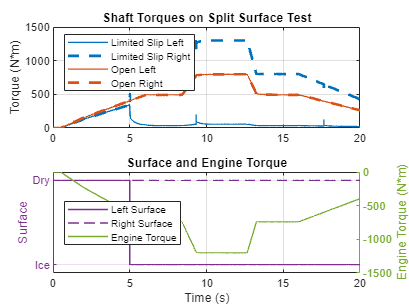

LimitedSlipDifferentialWithClutchesPlot2Torques;
subplot(2,1,1)      % Commands to ensure lower limit on y-axis is exactly 0
temp_ylim = ylim;
set(gca,'YLim',[0 temp_ylim(2)]);

*Copyright 2008-2017 The MathWorks, Inc.*